Calcium Analysis

Clear the workspace

clear all
clc


Import excel spreadsheet from ImageJ 

Frame    Cell 1    Cell 2    Etc

1            Value    Value    Value

2            Value    Value    Value

File = uigetfile('*.xlsx');
[Pre_data, Pre_headers] = xlsread(File);
Pre_headers = Pre_headers(2,:);
Data = Pre_data(:,3:end-1);
Data_headers = Pre_headers(1, 3:end-1);
Frame_column = Pre_data(:,1);
Frame_header = 'Frame';
[NumberofRows, NumberofColumns] = size(Data);
Max_value = max(max(Data));
Time = linspace(0, 5, NumberofRows);

fps = round(str2double(inputdlg('What is the fps rate?')));

**Plot Raw Data**

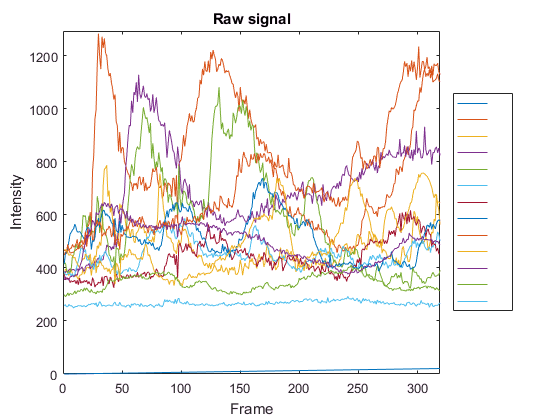

Figure1 = figure;
plot(Frame_column, Data)
axis([0 NumberofRows 0 Max_value+10])
title('Raw signal')
legend(Data_headers, 'Location', 'eastoutside')
ylabel('Intensity')
xlabel('Frame')

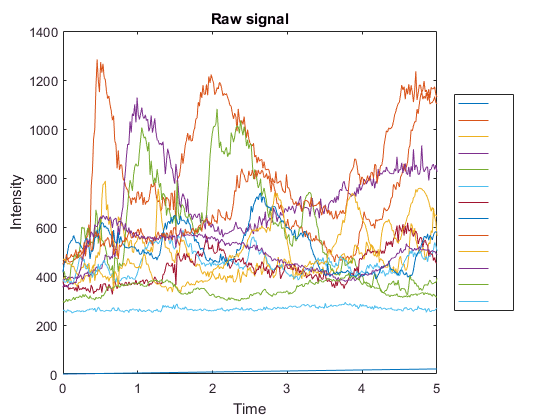


Figure2 = figure;
plot(Time, Data)
title('Raw signal')
legend(Data_headers, 'Location', 'eastoutside')
ylabel('Intensity')
xlabel('Time')

**Calculate the baseline for DF/F (average of first second (or 8 frames))**

Mean = mean(Data(1:15, :));

%plot specifications
Cell_ID = Data_headers';
Average_first_15_frames = Mean';
Table_1 = table(Cell_ID, Average_first_15_frames)

Table_1 =     Cell_ID    Average_first_15_frames
    _______    _______________________

    ''          0.455                 
    ''          465.2                 
    ''         377.71                 
    ''         391.29                 
    ''         437.78                 
    ''         394.32                 
    ''         353.19                 
    ''         514.42                 
    ''          480.4                 
    ''         440.31                 
    ''         372.63                 
    ''         304.64                 
    ''         256.25                 


## **Calculate dF/F (normalized data)**

DeltaFoverF = (Data - Mean)./Mean;

% Finds hidden mistakes in DF/F
for i = 1:NumberofColumns
    for j = 1:NumberofRows
        if DeltaFoverF(j,i)==9 | isnan(DeltaFoverF(j,i))
           error('Something is wrong')          
        end
    end
end

Something is wrong


Figure3 = figure;
plot(DeltaFoverF)
%plot specifications
axis([0 NumberofRows ylim])
title('\DeltaF/F');
xlabel('Frame');
ylabel('Intensity');

**Smooth data (temporal smoothing, window size = 1 second)**

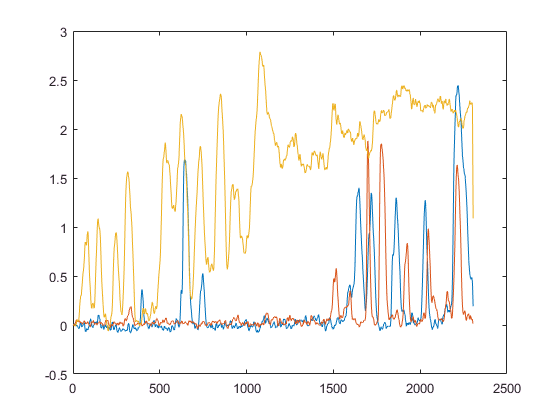

window = ones(fps,1)/fps;
Smoothed = convn(DeltaFoverF, window, 'same');
Figure5 = figure;
plot(Smoothed)

**Find all peaks and valleys in DF/F**

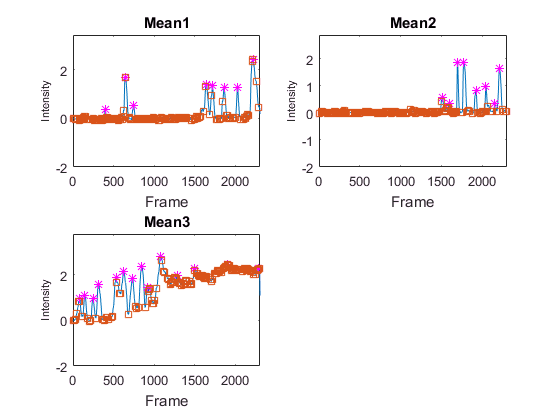

%finds all peaks and all valleys in Smoothed DF/F
for i = 1:NumberofColumns
    [allpeaks{i}, allpeaklocs{i}] = findpeaks(+Smoothed(:,i), 'MinPeakProminence', 0.25, 'MinPeakDistance', 30);
    [allvalleys{i}, allvalleylocs{i}] = findpeaks(-Smoothed(:,i));
    allvalleysneg{1,i} = -allvalleys{1,i};
end

%all graphs of all peaks and valleys
Dimensionofsubplots = ceil(sqrt(NumberofColumns));
Figure6 = figure;
for i = 1:NumberofColumns
    subplot2 = subplot(Dimensionofsubplots, Dimensionofsubplots, i);
    plot(Frame_column, Smoothed(:,i))
    hold on
    plot(allpeaklocs{1,i}, allpeaks{1,i}, '*m');
    plot(allvalleylocs{1,i}, allvalleysneg{1,i}, 'sq');
    hold off

    %plot specifications
    Max_value_subplot = max(max(Smoothed(:,i)));
    axis([0 NumberofRows -2 Max_value_subplot+1]);
    title(Data_headers(i));
    xlabel('Frame');
    ylabel('Intensity', 'FontSize', 8)
end

Finds peaks and its characteristics using findpeaks function 

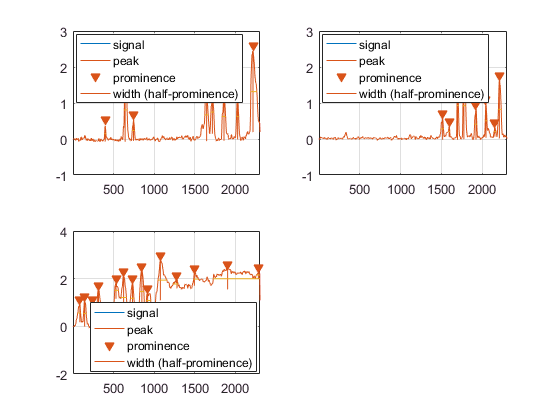

for i = 1:NumberofColumns
    [maxvalue, location, width, prominence] = findpeaks(Smoothed(:,i), 'MinPeakProminence', 0.25, 'MinPeakDistance', 30, 'Annotate', 'extents');
end

%plot examples
Figure7 = figure;
for i = 1:NumberofColumns
    subplot3 = subplot(Dimensionofsubplots, Dimensionofsubplots, i);
    plot(Frame_column, Smoothed(:,i))
    hold on
    findpeaks(Smoothed(:,i), 'MinPeakProminence', 0.25, 'MinPeakDistance', 30, 'Annotate', 'extents')
end